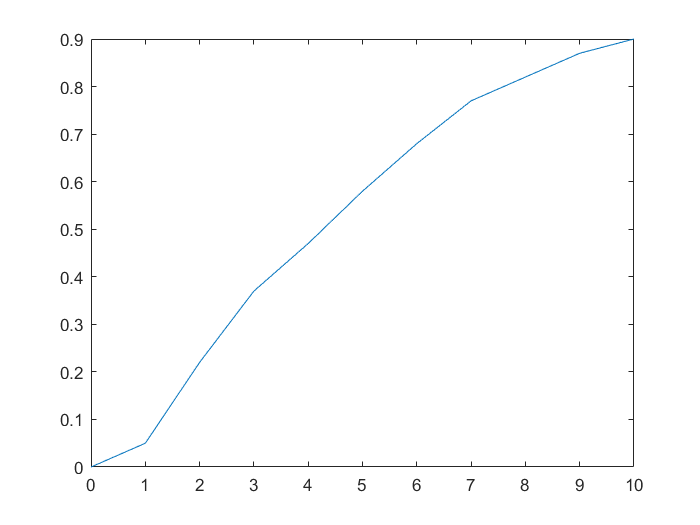

time = 0:10;
points = [0.0;0.05;0.22;0.37;0.47;0.58;0.68;0.77;0.82;0.87;0.90];
plot(time,points)

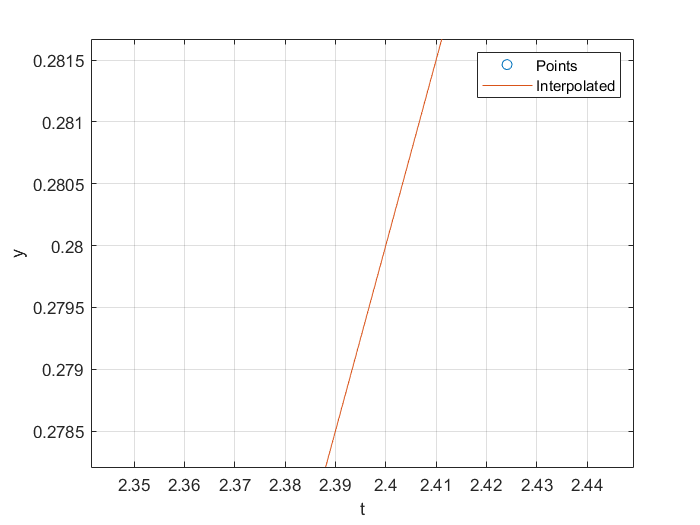

interpTime = 0:10^-5:10;
interpData = interp1(time, points, interpTime);
plot(time, points, 'o', interpTime, interpData, '-');
legend('Points', 'Interpolated');
xlabel('t');
ylabel('y');
grid on

k = 1;
y_inf=k;
max_slope = find_max_slope(points, time);
disp(['Max Slope: ', num2str(max_slope)]);

Max Slope: 0.17


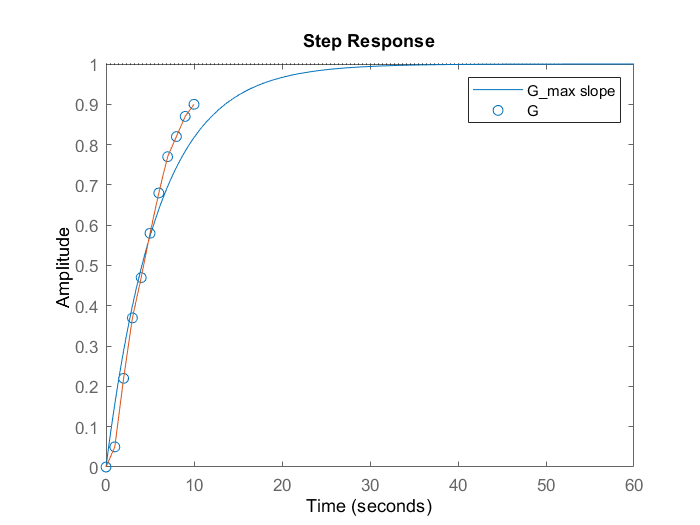






G1 = tf([k],[5.88 1]);
G2 = tf([k],[5.5 1]);
G3 = tf([k],[4.65 1]);
figure
[Y1,~] = step(G1,time);
step(G1)
hold on
plot(time, points, 'o', interpTime, interpData, '-');
legend("G_max slope","G")

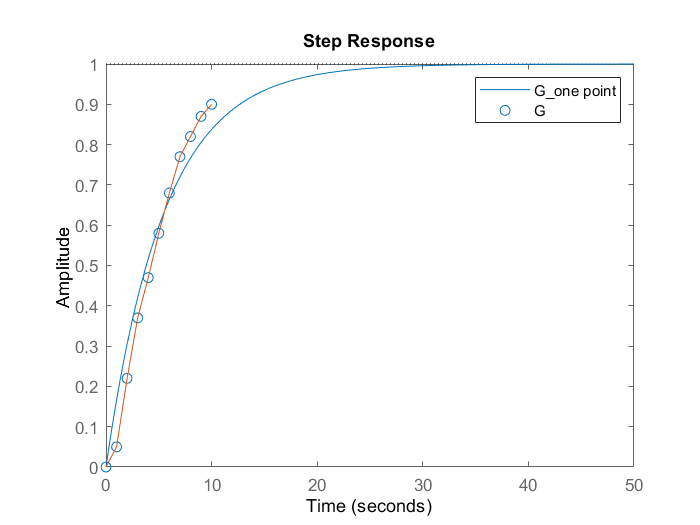



figure
[Y2,~] = step(G2,time);
step(G2)
hold on
plot(time, points, 'o', interpTime, interpData, '-');
legend("G_one point","G")

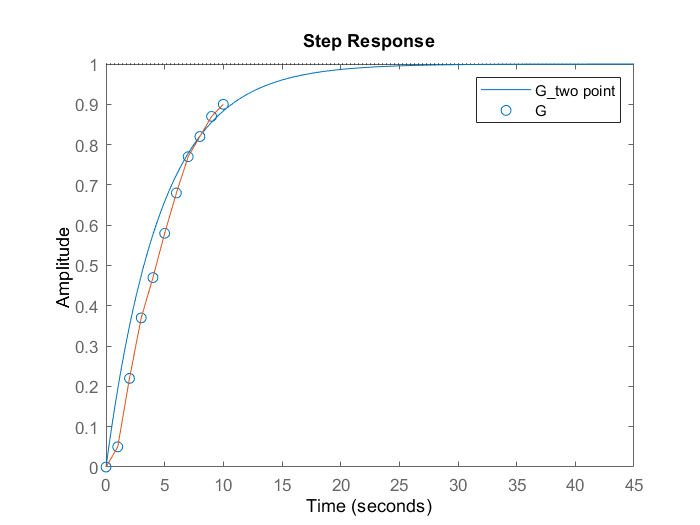


figure
[Y3,~] = step(G3,time);
step(G3)
hold on
plot(time, points, 'o', interpTime, interpData, '-');
legend("G_two point","G")

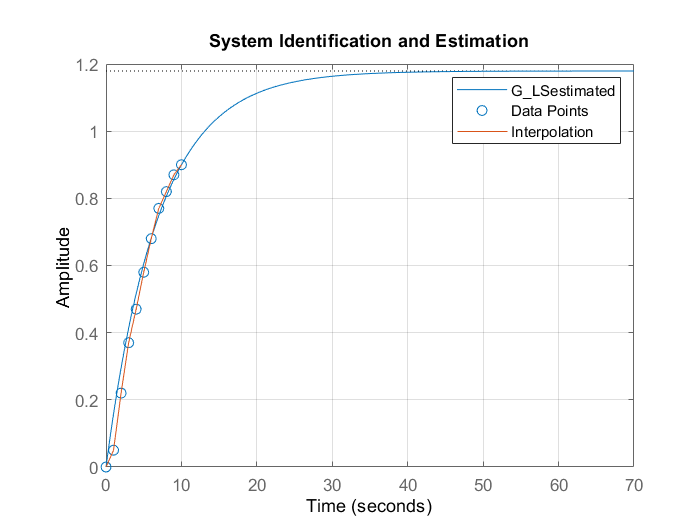

figure
% Create a list with 1 repeated 10 times
u = repmat(1, 1, 10);
u = [0.5, u];

% Initialize PHI matrix
PHI = [0 0; zeros(10, 2)];

% Populate PHI matrix
for i = 1:10
    phi = [-points(i) u(i)];
    PHI(i+1, :) = phi;
end

% Transpose PHI matrix
PHI_transpose = PHI.';

% Calculate theta using least squares method
theta = (inv(PHI_transpose * PHI)) * PHI_transpose * points(1:11);

% Extract coefficients from theta
a1 = theta(1);
a2 = theta(2);

% Calculate tau_LS and k_LS
tau_LS = 1 / (1 + a1);
k_LS = a2 / (1 + a1);

% Plotting
figure;

% Define transfer function
s = tf('s');
Numerator = [k_LS];
Denominator = [tau_LS, 1];
G_estimated = tf(Numerator, Denominator);

% Simulate and plot the response
[Y_LSestimated, ~] = step(G_estimated, time);
step(G_estimated);
hold on;

% Plot data points and interpolation
plot(time, points, 'o', interpTime, interpData, '-');

% Add legend
legend('G_{LSestimated}', 'Data Points', 'Interpolation');

% Add labels and title
xlabel('Time');
ylabel('Amplitude');
title('System Identification and Estimation');

% Display grid
grid on;

err_MS = mse(time.',Y1,points)

err_MS = 0.0041

err_OP = mse(time.',Y2,points)

err_OP = 0.0036

err_tP = mse(time.',Y3,points)

err_tP = 0.0062

err_LS = mse(time.',Y_LSestimated,points)

err_LS = 0.0021